clc
clear all
load('dataset1.mat')
load('dataset2.mat')

## K-means

X = dataset1;
k = 2;
no_iter = 50;
initializer = 1;

[c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);

Initializer: random


cost

cost = 9.1309e+03

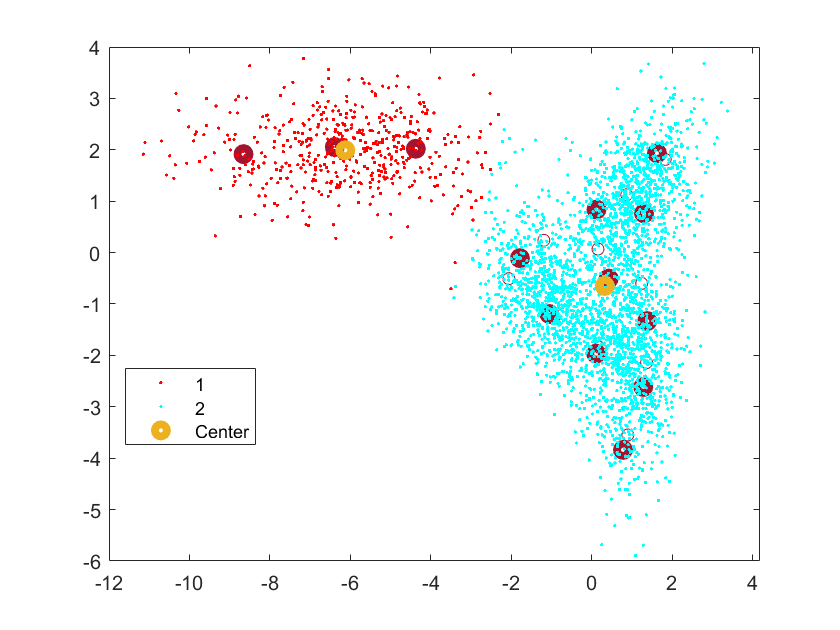

gscatter(X(:,1),X(:,2),c_idx)
hold on 
scatter(C(:,1),C(:,2),"LineWidth",4,"DisplayName",'Center')
hold off


all_cost = [];
for k = 2: 50
    COSTs = zeros(5,1);
    for i = 1:5
        [c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
        C_IDXs{i} = {c_idx};
        Cs{i} = {C};
        COSTs(i) = cost;
    end
    [M,IDX] = min(COSTs);
    all_cost = [all_cost;M];
end

Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random
Initializer: random


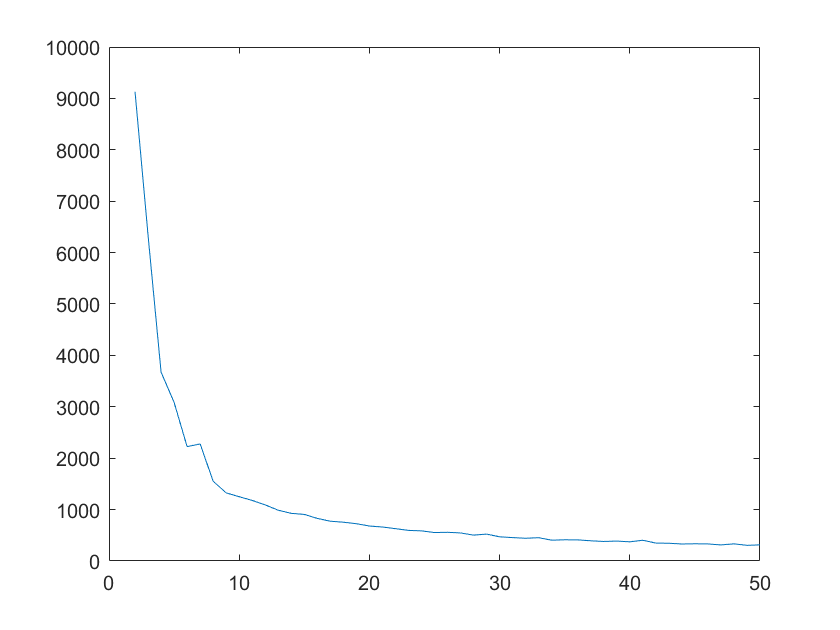

plot(2: 50,all_cost)

## K-means ++

initializer = 2;
[c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);

Initializer: k-means ++


cost

cost = 305.6044

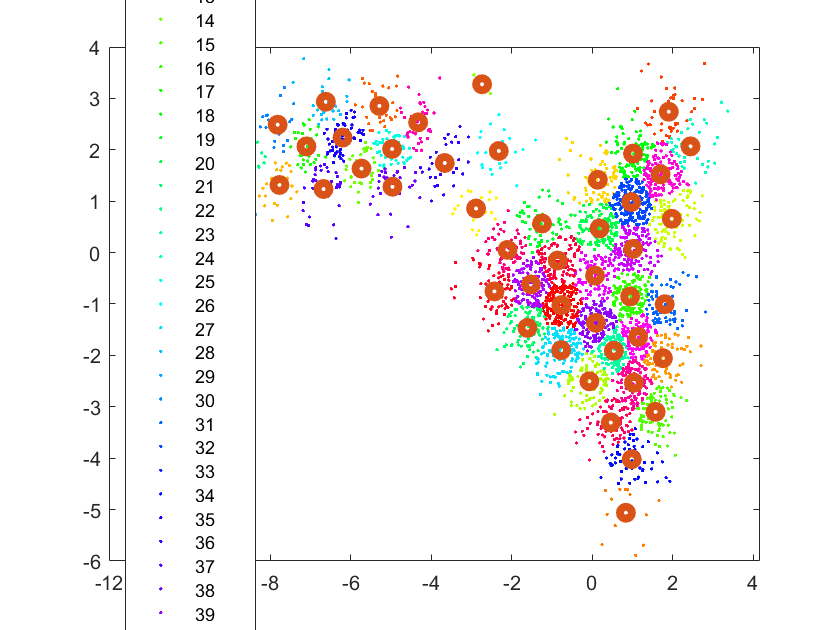

gscatter(X(:,1),X(:,2),c_idx)
hold on 
scatter(C(:,1),C(:,2),"LineWidth",4,"DisplayName",'Center')
hold off


all_cost = [];
for k = 2: 50
    COSTs = zeros(5,1);
    for i = 1:5
        [c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
        C_IDXs{i} = {c_idx};
        Cs{i} = {C};
        COSTs(i) = cost;
    end
    [M,IDX] = min(COSTs);
    all_cost = [all_cost;M];
end

Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++


plot(2: 50,all_cost)

# On test data set 2

X = dataset2;
k = 2;
no_iter = 50;

[c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);

Number of cluster should smaller than the input examples!
Initializer: k-means ++


cost

cost = 4.5152e+05

for i = 1:k
    data = X(c_idx==i,:);
    scatter3(data(:,1),data(:,2),data(:,3));
    hold on 
end

hold on 
scatter(C(:,1),C(:,2),"LineWidth",4,"DisplayName",'Center')
hold off

all_cost = [];
for k = 2: 50
    COSTs = zeros(5,1);
    for i = 1:5
        [c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
        C_IDXs{i} = {c_idx};
        Cs{i} = {C};
        COSTs(i) = cost;
    end
    [M,IDX] = min(COSTs);
    all_cost = [all_cost;M];
end

Number of cluster should smaller than the input examples!
Initializer: k-means ++
Number of cluster should smaller than the input examples!
Initializer: k-means ++
Number of cluster should smaller than the input examples!
Initializer: k-means ++
Number of cluster should smaller than the input examples!
Initializer: k-means ++
Number of cluster should smaller than the input examples!
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++
Initializer: k-means ++


plot(2: 50,all_cost)



% ++ init
initializer = 2;
[c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
cost
for i = 1:k
    data = X(c_idx==i,:);
    scatter3(data(:,1),data(:,2),data(:,3));
    hold on 
end
scatter(C(:,1),C(:,2),"LineWidth",4,"DisplayName",'Center')
hold off
all_cost = [];
for k = 2: 50
    COSTs = zeros(5,1);
    for i = 1:5
        [c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
        C_IDXs{i} = {c_idx};
        Cs{i} = {C};
        COSTs(i) = cost;
    end
    [M,IDX] = min(COSTs);
    all_cost = [all_cost;M];
end
plot(2: 50,all_cost)


# Agglomerative hierarchical cluster tree

## Data set 1

X = dataset1;
Z = linkage(X,'average')

Z = 	1.0e+03 *

    1.6220    1.7110    0.0000
    0.7360    0.8030    0.0000
    2.0220    2.8760    0.0000
    0.7240    0.7980    0.0000
    2.5970    2.9230    0.0000
    2.3170    2.9930    0.0000
    1.5710    2.8940    0.0000
    0.6820    0.6900    0.0000
    0.5870    0.9100    0.0000
    1.1210    2.9330    0.0000


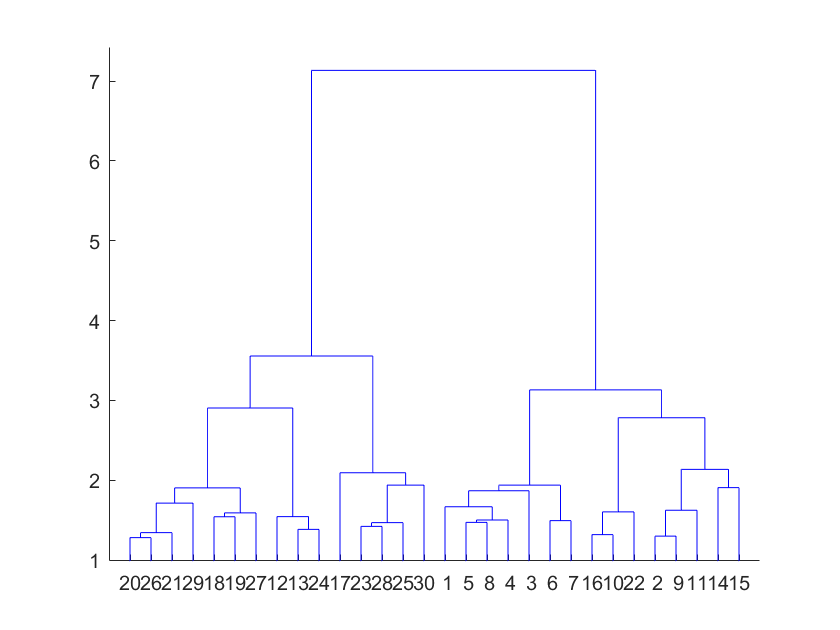

dendrogram(Z)

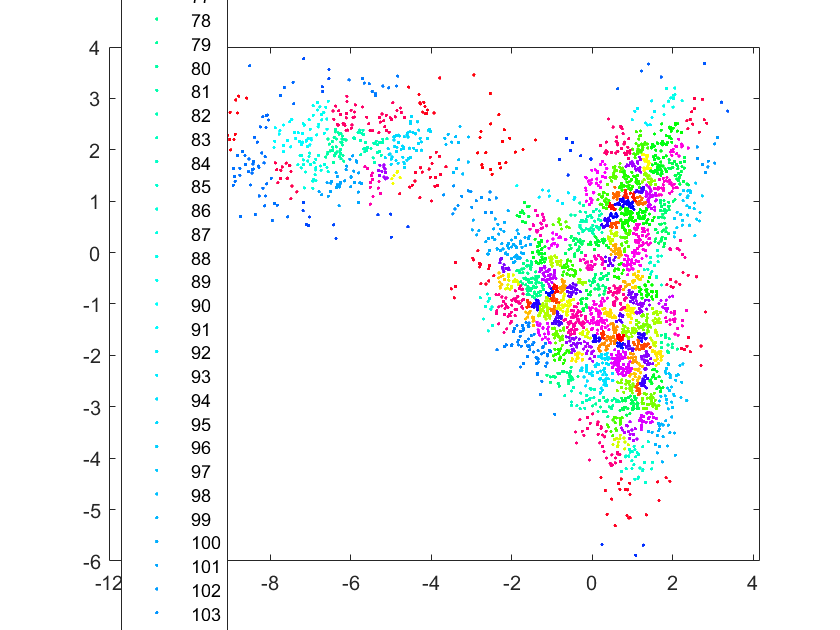

T = cluster(Z,'Cutoff',2.5,'Depth',4);
gscatter(X(:,1),X(:,2),T)

Z = linkage(X,'single')

Z = 	1.0e+03 *

    1.6220    1.7110    0.0000
    0.7360    0.8030    0.0000
    2.0220    2.8760    0.0000
    0.7240    0.7980    0.0000
    2.5970    2.9230    0.0000
    2.3170    2.9930    0.0000
    1.5710    2.8940    0.0000
    0.6820    0.6900    0.0000
    0.5870    0.9100    0.0000
    1.1210    2.9330    0.0000


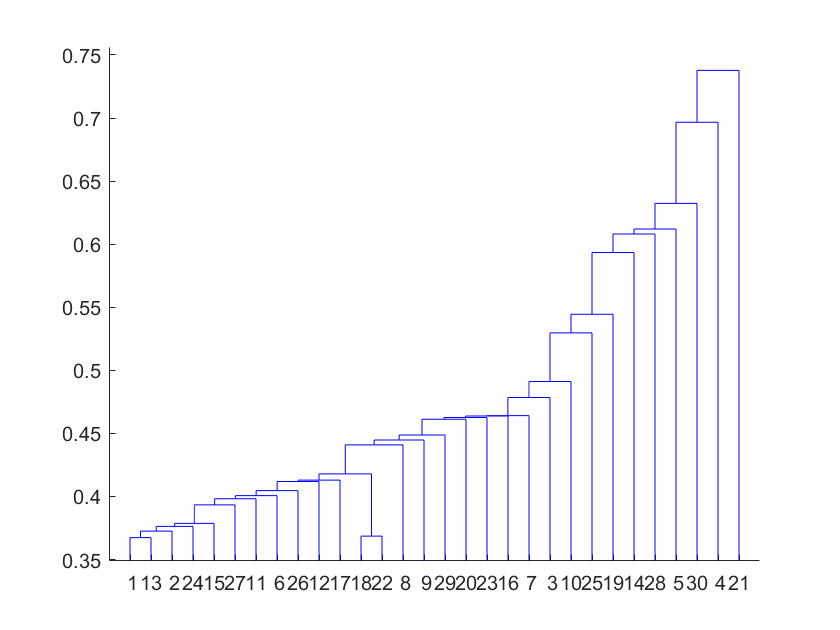

dendrogram(Z)

## Data set 2

X = dataset2;
Z = linkage(X,'average')
dendrogram(Z)
Z = linkage(X,'single')
dendrogram(Z)

## tesing

[c_idx,C] = kmeans(X,k)

c_idx =     22
    38
    34
    20
     2
    44
    22
    35
    19
     6


C =    -0.8713    9.8670   -5.0898
    5.9790    2.8098    1.9551
   11.8439   10.6824   -2.7622
    2.7913   16.5965    8.6093
    7.3998    8.9274   -0.1677
    2.9013   17.1259  -10.7326
   -4.4313    3.1175   -9.2629
   -3.0815   15.5953   -3.6717
    7.2199   13.4452   -1.5269
   11.5506    3.0768    5.1542


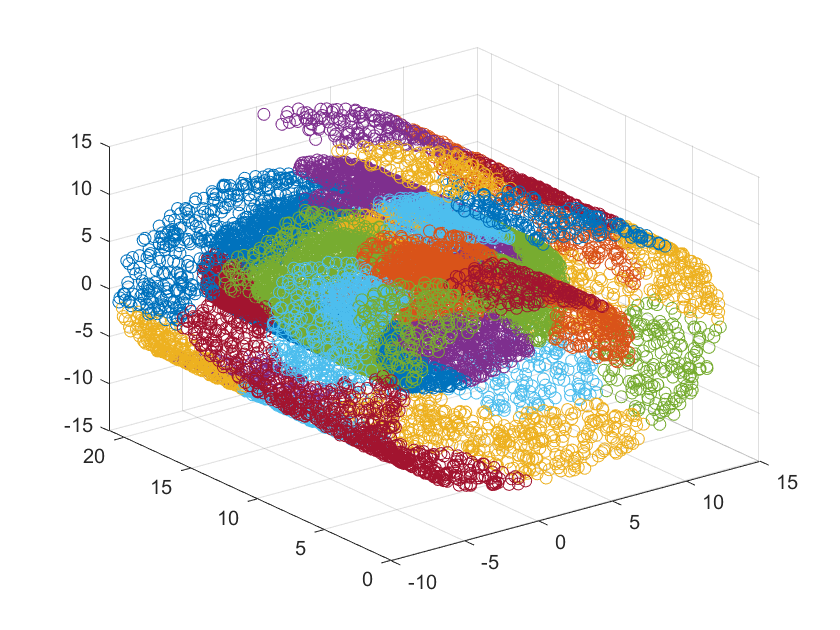

for i = 1:k
    data = X(c_idx==i,:);
    scatter3(data(:,1),data(:,2), data(:,3))
    hold on
end
hold off